% Download FRED data (A939RX0Q048SBEA = Real GDP per capita)
url = 'https://fred.stlouisfed.org/graph/fredgraph.csv?id=A939RX0Q048SBEA';
filename = 'rgdp_pc.csv';
websave(filename, url);

% comment out above once data is downloaded and saved

% Read the data
data = readtable(filename);
data = data(:, {'observation_date', 'A939RX0Q048SBEA'});
data.Properties.VariableNames = {'Date', 'RGDPpc'};
data.Date = datetime(data.Date, 'InputFormat', 'yyyy-MM-dd');
data = rmmissing(data);  % drop missing values

% Log of real GDP per capita
log_rgdp = log(data.RGDPpc);

% Log-differencing
log_diff = [NaN; diff(log_rgdp)];

% Linear detrending 
% NOTE: this is a manual example
% you can linearly detrend using hpfilter function (below) by setting
% smoothing paramter to 'inf'
t = (1:length(log_rgdp))';
X = [ones(size(t)), t];
b = X \ log_rgdp;
trend = X * b;
detrended = log_rgdp - trend;

% Plotting
figure('Position', [100, 100, 1000, 400])

subplot(1,2,1)
plot(data.Date, log_diff, 'b')
title('Log-Differenced Real GDP per Capita')
ylabel('Growth Rate (log diff)')
xlabel('Date')
% legend('Location','best')
grid on

subplot(1,2,2)
plot(data.Date, detrended, 'r')
title('Linear Detrended Log Real GDP per Capita')
ylabel('Deviation from Log-Linear Trend')
xlabel('Date')
% legend('Location','best')
grid on

sgtitle('US Real GDP per Capita: Transformation Comparison')

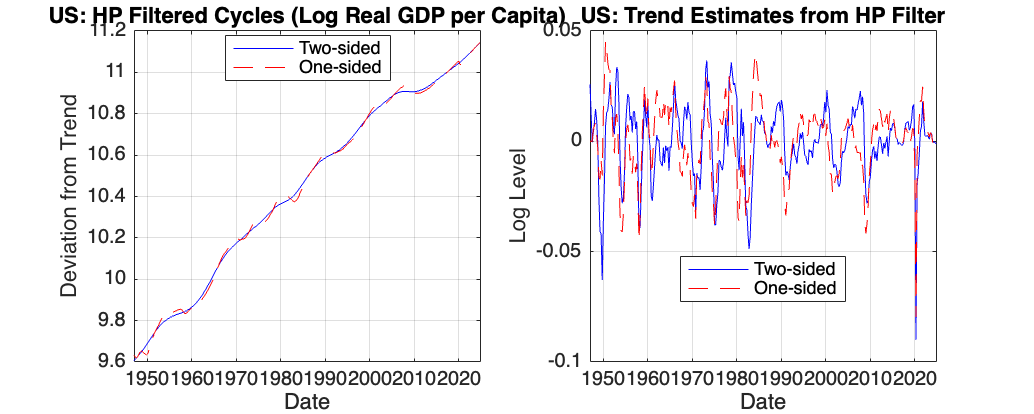

% Download U.S. real GDP per capita data from FRED
url_us = 'https://fred.stlouisfed.org/graph/fredgraph.csv?id=A939RX0Q048SBEA';
filename_us = 'us_rgdp_pc.csv';
websave(filename_us, url_us);

% Read and log-transform the data
us_data = readtable(filename_us);
us_data = us_data(:, {'observation_date', 'A939RX0Q048SBEA'});
us_data.Properties.VariableNames = {'Date', 'RGDPpc'};
us_data.Date = datetime(us_data.Date, 'InputFormat', 'yyyy-MM-dd');
us_data = rmmissing(us_data);
log_us = log(us_data.RGDPpc);

% Apply two-sided HP filter
[cycle_hp, trend_hp] = hpfilter(log_us, Smoothing=1600);  % Quarterly lambda = 1600

% One-sided HP filter (recursive estimation)
trend_one_sided_manual = NaN(size(log_us));
for t = 8:length(log_us)
    [~, trend_temp] = hpfilter(log_us(1:t), Smoothing=1600);
    trend_one_sided_manual(t) = trend_temp(end);
end
cycle_one_sided_manual = log_us - trend_one_sided_manual;

[cycle_one_sided, trend_one_sided] = hpfilter(log_us, Smoothing=1600, FilterType="one-sided");

% Plotting
figure('Position', [100, 100, 1000, 400])
subplot(1,2,1)
plot(us_data.Date, cycle_hp, 'b', 'DisplayName', 'Two-sided')
hold on
plot(us_data.Date, cycle_one_sided, 'r--', 'DisplayName', 'One-sided')
title('US: HP Filtered Cycles (Log Real GDP per Capita)')
ylabel('Deviation from Trend')
xlabel('Date')
legend('Location','best')
grid on

subplot(1,2,2)
plot(us_data.Date, trend_hp, 'b', 'DisplayName', 'Two-sided')
hold on
plot(us_data.Date, trend_one_sided, 'r--', 'DisplayName', 'One-sided')
title('US: Trend Estimates from HP Filter')
ylabel('Log Level')
xlabel('Date')
legend('Location','best')
grid on
hold off

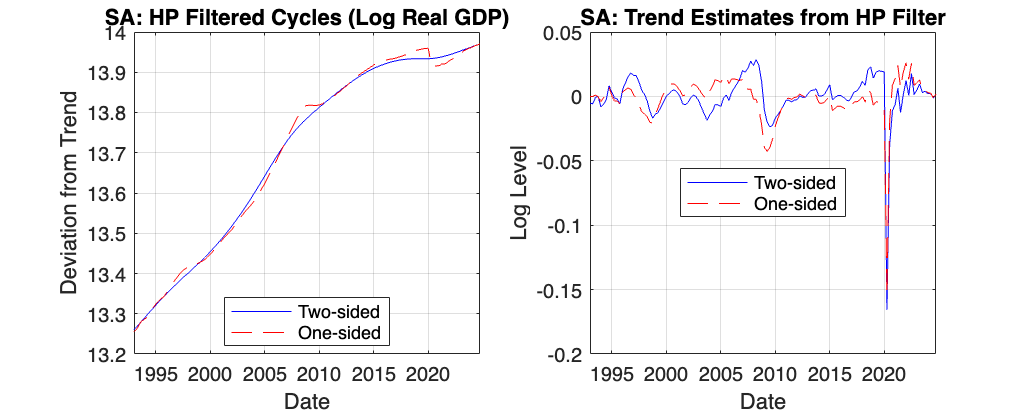

% Download South Africa real GDP (constant prices) from FRED
url_sa = 'https://fred.stlouisfed.org/graph/fredgraph.csv?id=NGDPRSAXDCZAQ';
filename_sa = 'sa_rgdp.csv';
websave(filename_sa, url_sa);

% Read and log-transform the data  (growth rate: NAEXKP01ZAQ657S)
sa_data = readtable(filename_sa);
sa_data = sa_data(:, {'observation_date', 'NGDPRSAXDCZAQ'});
sa_data.Properties.VariableNames = {'Date', 'RGDP'};
sa_data.Date = datetime(sa_data.Date, 'InputFormat', 'yyyy-MM-dd');
sa_data = rmmissing(sa_data);
log_sa = log(sa_data.RGDP);

% Two-sided HP
[cycle_sa_hp, trend_sa_hp] = hpfilter(log_sa, Smoothing=1600);

% One-sided HP
trend_sa_1s = NaN(size(log_sa));
for t = 8:length(log_sa)
    [~, trend_temp] = hpfilter(log_sa(1:t), Smoothing=1600);
    trend_sa_1s(t) = trend_temp(end);
end
cycle_sa_1s = log_sa - trend_sa_1s;

[cycle_sa_one_sided, trend_sa_one_sided] = hpfilter(log_sa, Smoothing=1600, FilterType="one-sided");

% Plotting
figure('Position', [100, 100, 1000, 400])
subplot(1,2,1)
plot(sa_data.Date, log_sa - trend_sa_hp, 'b', 'DisplayName', 'Two-sided')
hold on
% plot(sa_data.Date, cycle_sa_1s, 'r--', 'DisplayName', 'One-sided')
plot(sa_data.Date, cycle_sa_one_sided, 'r--', 'DisplayName', 'One-sided')
title('SA: HP Filtered Cycles (Log Real GDP)')
ylabel('Deviation from Trend')
xlabel('Date')
legend('Location','best')
grid on

subplot(1,2,2)
plot(sa_data.Date, trend_sa_hp, 'b', 'DisplayName', 'Two-sided')
hold on
% plot(sa_data.Date, trend_sa_1s, 'r--', 'DisplayName', 'One-sided')
plot(sa_data.Date, trend_sa_one_sided, 'r--', 'DisplayName', 'One-sided')
title('SA: Trend Estimates from HP Filter')
ylabel('Log Level')
xlabel('Date')
legend('Location','best')
grid on

% save the workspace to a .mat file
% save rbc_tutorial_data % remove comment 
% to load data simply enter command: load rbc_tutorial_data